# **IIR Notch Filter**

## **I. Introduction**

    Many occasions by a digital filter to filter out certain frequency noise, for example, in the detection of weak signal, often have 50Hz power interference signal, and as in audio amplifier speakers close to the microphone, will produce a self feedback whistle signal. These noise signal is harmful, while retaining the original signal at the same time, how to eliminate interference, the main purpose is to design a filter. Notch filter is of certain frequency of the signal are eliminated, and the other components of the signal is not affected.

    The advantages of IIR filters is its frequency response is most like the analog filter, lower order than FIR filter for the frequency response effiectivity. So that, it's very suitable for embedded system which has limit resources.

## **II. Theory**

### **a. IIR Filter**

    As mentioned above, an ideal notch filter frequency response:


$$H\left(s\right)=\left\lbrace \begin{array}{ll}
0, & \omega_{0\;} \\
1, & \textrm{otherwise}
\end{array}\right.$$


wherein, $\omega_{0\;}$is notch filter center frequency.

    Unlike FIR filters, in which the output is calculated only on the basis of present and past inputs, IIR filters also take into account the filter’s past output. This turns the behavior of the filter into a recursive one. The feedback mechanism provides a faster response time. They are intended for programs that do not require a linear phase.  

    The transfer function of IIR filters in $z-\textrm{domain}$ is given below:


$$H\left(z\right)=\frac{\sum_{k=0}^M b_k {\cdot \;z}^{-k\;} }{1+\sum_{k=1}^N a_k {\cdot \;z}^{-k\;} }$$


and the output is computed as:


$$y\left\lbrack n\right\rbrack =-\sum_{k=1}^N a_k \cdot y\left\lbrack n-k\right\rbrack +\sum_{k=0}^M b_k \cdot x\left\lbrack n-k\right\rbrack$$


    IIR filters can be represented by structures such as Direct form I, Normal and Transposed Direct form II, Cascade, Latice. The simplest form for implementation is Direct form I (image below).

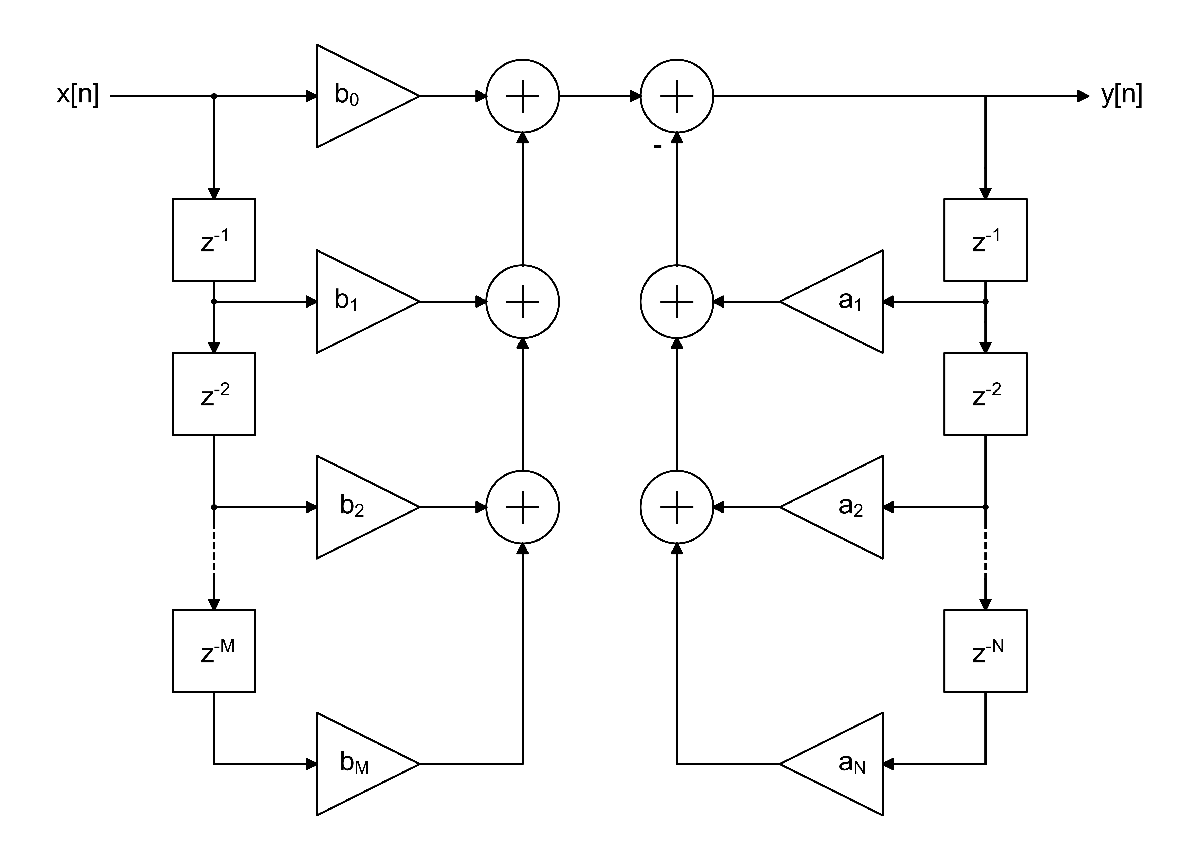

**Direct form 1 of IIR Filter.**

**b. Second-order Notch Filter**

    The basic idea of a notch filter is to have a pole for every zero.


$$H\left(z\right)=\frac{1-rz^{-1} }{1-pz^{-1} },\;\;\;\;\;\;\;\;\left|H\left(\omega \right)\right|=\frac{\left|1-r\;e^{-j\omega \;} \right|}{\left|1-p\;e^{-j\omega \;} \right|}$$


an then choose $r=e^{j\omega_c }$,$p=a\;e^{j\omega {\;}_c }$, for some a that is very close to $1\ldotp 0$. That way,

- When $\omega =\omega {\;}_c$, the mumerator is exactly


$$\left|1-e^{{j\omega \;}_c \;} \cdot e^{-j\omega {\;}_{c\;} } \right|=\left|1-1\right|=0$$


- When $\omega \not= \omega {\;}_{c\;}$,

$\left|1-e^{j\omega {\;}_c } \cdot e^{-j\omega } \right|\approx \left|1-{a\;e}^{j\omega {\;}_c } \cdot e^{-j\omega } \right|$, so $\left|H\left(\omega \;\right)\right|\approx 1$

but the problem is $r$ and$p$ are both complex, therefore, even if the input is real, the output will be complex.

    To get real-valued coefficients, we have to use a second-order filter with conjugate poles and zeros ($r_2 =r_1^* =e^{-j\omega_c }$, and$p_2 =p_1^* =a\;e^{-j\omega {\;}_c }$):


$$\begin{array}{l}
H\left(z\right)=\frac{\left(1-r_1 z^{-1} \right)\left(1-r_1^* z^{-1} \right)}{\left(1-p_1 z^{-1} \right)\left(1-p_1^* z^{-1} \right)}\\
=\frac{1-2\cos \omega_c z^{-1} +z^{-2} }{1-2\cos \omega_c z^{-1} +{a^2 z}^{-2} }
\end{array}$$


So then, we can implement it as a second-order difference equation:


$$y\left\lbrack n\right\rbrack =x\left\lbrack n\right\rbrack -2\cos \omega_c x\left\lbrack n-1\right\rbrack +x\left\lbrack n-2\right\rbrack +2\mathrm{acos}\omega_c y\left\lbrack n-1\right\rbrack -a^2 y\left\lbrack n-2\right\rbrack$$


## **III. Implementation**

For example, the design of a center frequency of $f_c =50\textrm{Hz}$ notch filter, filter the AC power line interference. Effective signal maximum frequency of $100\textrm{Hz}$, and a sampling frequency $f_s =1\textrm{kHz}$, $a=0\ldotp 99$ , MATLAB simulation procedure is as follows:

fs = 1000;
fc = 50;
b0 = 1;
b1 = -2*cos(2*pi*fc/fs);
b2 = 1;
r = 0.99;
a0 = 1;
a1 =-2*r*cos(2*pi*fc/fs)

a1 = -1.8831

a2 = r*r;
b = [b2,b1,b0];
a = [a2,a1,a0];
[h,w] = freqz(b,a);
hf = abs(h);
argf = angle(h);

figure(1);
plot(w*fs/(2*pi),hf);
xlim([0 150]);
title('Magnitude Response');
xlabel('Freguency in Hz');

figure(2);
plot(w*fs/(2*pi),argf);
xlim([0 150]);
title('Phase Response');
xlabel('Freguency in Hz');

figure(3);
zplane(b,a);legend('zero','plot');